## Basis matrices en rijen

Matlab werkt voornamelijk met matrices en rijen. Om deze aan te maken en te bewerken kan je gebruik maken van onderstaande commando's. Om in Matlab de output van een lijn te onderdrukken plaats je een ; aan het eind. 

V1 = [1 2 3 5] + 1i*[-1 2 3 -5] % aanmaken van een complexe rij vector

V1 =   1.000000000000000 - 1.000000000000000i  2.000000000000000 + 2.000000000000000i  3.000000000000000 + 3.000000000000000i  5.000000000000000 - 5.000000000000000i


V1H = V1' % bereken de complex toegevoegde + getransponeerde 

V1H =   1.000000000000000 + 1.000000000000000i
  2.000000000000000 - 2.000000000000000i
  3.000000000000000 - 3.000000000000000i
  5.000000000000000 + 5.000000000000000i


V1T = V1.' % bereken de getransponeerde

V1T =   1.000000000000000 - 1.000000000000000i
  2.000000000000000 + 2.000000000000000i
  3.000000000000000 + 3.000000000000000i
  5.000000000000000 - 5.000000000000000i


M1 = [[1 2 3];[4 5 6];[7 8 9]] % aanmaken van een 3x3 matrix

M1 =      1     2     3
     4     5     6
     7     8     9


M2 = ones(3,5) % aanmaken matrix met enkel enen

M2 =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


M3 = zeros(5,3) % aanmaken matrix met enkel nullen

M3 =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


M4 = eye(5) % aanmaken identiteitsmatrix

M4 =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


V2 = -1:0.1:1 % aanmaken vector van -1 tot 1 in stappen van 0.1

V2 =   -1.000000000000000  -0.900000000000000  -0.800000000000000  -0.700000000000000  -0.600000000000000  -0.500000000000000  -0.400000000000000  -0.300000000000000  -0.200000000000000  -0.100000000000000                   0   0.100000000000000   0.200000000000000   0.300000000000000   0.400000000000000   0.500000000000000   0.600000000000000   0.700000000000000   0.800000000000000   0.900000000000000   1.000000000000000


M4_sub = M4(2:end,3:5) % submatrix selecteren uit een matrix

M4_sub =      0     0     0
     1     0     0
     0     1     0
     0     0     1


M4_sub = M4(2:end,3:5); % submatrix selecteren uit een matrix zonder output
M4_error = M4(0:end,1) % index start bij 1

Subscript indices must either be real positive integers or logicals.


## Basis bewerkingen

Vsum = V1H + V1T % som van twee vectoren/matrices - dimensies moeten uiteraard kloppen

Vsum =      2
     4
     6
    10


Mprod = M1*M2 % matrixproduct - dimensies moeten uiteraard kloppen

Mprod =      6     6     6     6     6
    15    15    15    15    15
    24    24    24    24    24


Mprod_element = M1.*eye(3) % elementsgewijze vermenigvuldiging (./ is elementsgewijze deling)

Mprod_element =      1     0     0
     0     5     0
     0     0     9


Mprod_square = M1.^2 % elementsgewijze machtsverheffing

Mprod_square =      1     4     9
    16    25    36
    49    64    81


N_elementen = numel(Mprod_element) % geeft het aantal elementen in een Matrix/vector

N_elementen =      9


size(M3) % geeft de dimensie van een matrix 

ans =      5     3


length(M3) % geeft grootste dimensie van een matrix 

ans =      5


reshape(Mprod,5,3) % vervorm matrix

ans =      6    24    15
    15     6    24
    24    15     6
     6    24    15
    15     6    24


sum(V1) % geeft de som van alle elementen van een vector of matrix

ans =  11.000000000000000 - 1.000000000000000i


min(M1) % bereken minimum 

ans =      1     2     3


max(M1(:)) % bereken maximum

ans =      9


find([0 1 2 4 0 -1 0 4]) % geeft index van alle niet nul elementen

ans =      2     3     4     6     8


[sorted,index]= sort([-1 4 8 6 3 -5 -7]); % sorteert een rij
sorted

sorted =     -7    -5    -1     3     4     6     8


index

index =      7     6     1     5     2     4     3


de2bi(18,6) % zet getal om in bitsequentie

ans =      0     1     0     0     1     0


bi2de([1 1 0 0 1 1]) % zet bitsequentie om in getal

ans =     51


## Cell arrays

Een cell arrys in Matlab is matrix/vector van cellen. Een cell zelf kan alle datatypes bevatten zoals matrices, vectors, text.  In tegenstelling tot een normale matrix kan de inhoud van een element van een cell array iets anders zijn dan een scalair. Een Cell array is dan ook handig om vectoren en matrices van verschillende dimensies op te slaan. 

C = {1,ones(4,4),eye(2),[77;78],'text'}
C(4) % vierde cell van C
C{4} % inhoud vierde cell van C


## Lussen en if-else

In Matlab kan je heel eenvoudig gebruik maken van lussen (for, while) en de if-else structuur. Bemerk wel dat Matlab vaak aanzienlijk sneller is al je de bewerkingen implementeert met matrices in plaats van met lussen. 

for i = 1 : 10
    x = randn(1) % genereer een random getal volgens de normale verdeling
    if(x>=0)
        disp('x is positief')
    else
        disp('x is negatief')
    end
end

## Figuren maken

Matlab kan ook data visueel voorstellen met de behulp van de functies: plot, histogram, bar, ...

figure() % maak een nieuwe figuur
x = -2*pi:0.001:2*pi; % vector van x-waarden
y1 = cos(x); % vector van y-waarden
y2 = exp(x/10); % tweede vector van y-waarden
plot(x,y1,'r') % plot y in functie van x in het rood ('r')
hold on % als je meerdere lijnen op één plot wilt weergeven - andere optie is plot(x,y1,x,y2)
plot(x,y2,'b')
% opmaak van de figuur
xlim([-2*pi 2*pi])
xlabel('x')
ylabel('y')
grid on
legend('cosinus','exponentiële')

Ook een logaritmische figuur is mogelijk 

figure()
semilogy(x,y2,'b')
xlabel('x')
ylabel('exp(x/10)')


## Anonieme functies

In Matlab kan je ook  een anonieme functie maken die dan net zoals andere functies één of meerdere inputs omzet in een output. De functie wordt dan in een variabele bewaard van het type *function_handle. *Een beperking is dat de definitie van de  anonieme functie wel maar één regel kan beslaan. 

sqr = @(x) x.^2; % definitie van anonieme functie sqr die het kwadraat berekent van een getal
sqr(0.124789)
c = @(a,b) sqrt(a.^2+b.^2) % kan ook meerdere inputs hebben
c(4,3)
x = 5;
const = 3;
d = @(x) x*const;

Deze anonieme functies zijn soms noodzakelijk om sommige functionaliteiten van Matlab te gebruiken. Een voorbeeld daarvan is de functie *integral() *die de integraal berekent van een anonieme functie.

integral(sqr,0,5) % bereken integraal van x^2 tussen grenzen 0 en 5
integral(@(x) x.^2,0,5) % de anomieme functie kan ook ter plaatste aangemaakt worden 

## Werken met audiofiles

In het project moet je een audiofile kunnen inlezen, afspelen en weer wegschrijven. Dit doe je in Matlab met de functies *audioread(), sound(), audiowrite().*

[audiosamples,samplerate] = audioread('input.wav'); % inlezen van audio - merk op dat sommige functies meerdere variabelen als output kan hebben
%sound(audiosamples,samplerate);
audiowrite('output.wav',audiosamples,samplerate)

## Veelterm-vermenigvuldiging en deling met conv en deconv

Vermenigvuldigen van veeltermen kan je bereken door middel van een convolutie. Bijvoorbeeld


$$(x^4+x^2+5x +2)*(2x^3+x+1)=2x^7+3x^5+11x^4+5x^3+6x^2+7x+2$$


Analoog kan de deling berekenen met de functie deconv:


$$(x^4+x^2+5x +2)/(2x^3+x+1)=\frac{1}{2}x(2x^3+x+1)+\frac{1}{2}x^2+\frac{9}{2}+2$$


conv([1 0 1 5 2],[2 0 1 1])
[Q,R] = deconv([1 0 1 5 2],[2 0 1 1])


## Werken met klassen

Matlab biedt zoals andere programeertalen ook de mogelijkheid aan om te werken met klassen. Hier wordt de code van een eenvoudige klasse weergegeven. 

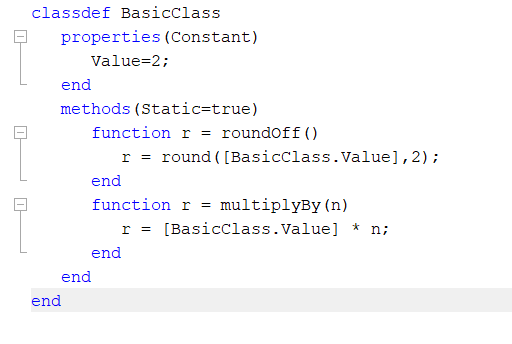

Oproepen van de statische methodes gebeurt dan als volgt

 r = BasicClass.multiplyBy(5)

## Data opslaan

save('datafile','M1');
M1 = 0;
load('datafile')
M1